# LME testing the effect of K vs S on the PCA dimensions of vocalizations for 4 acoustic groups

here we are using now the clustering obtained with the 10 dimensions UMAP calculated in Notebbok 8ter instead of the clustering obtained with the 3 dimensions UMAP calculated in Notebook 8. The optimization of the number of dimensions for the UMAP clustering performance was done by looking at median values of Silhouette (notebook 8ter)

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
BaseDataDir = '/Volumes/server_home/users/JulieE/DeafSalineGroup151/';
BaseCodeDir = '/Users/elie/Documents/CODE/GitHub/';
BoxPath = '/Users/elie/Box';
Path2Paper = fullfile(BoxPath, 'BatmanData', 'Deaf Paper');

Loading previous data

load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls2.mat'),'BatID','MicAudioGood','MPS_mic', 'MPS_mic_wf', 'MPS_mic_wt')
%load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'MicAudioGood','TmicAll7');
load(fullfile(BaseDataDir, 'Data4_DeafBats_CatCalls_UMAPMic.mat'), 'TmicAll4');
MicAudioGood01 = MicAudioGood;
MicAudioGood01(isnan(MicAudioGood01)) = 0;
MicAudioGood01 = logical(MicAudioGood01);

Get the color vector ready for BatName, Sex and Deafness

ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
Path2RecordingTable = fullfile(BoxPath,'JuvenileRecordings/DeafRecordingsNWAF155_Log.xlsx');
[~,~,RecTableData]=xlsread(Path2RecordingTable,2,'A1:k3','basic');
BatName = cell2mat(RecTableData(3,2:11));
BatSexDeaf = cell(size(BatName));
CSexDeaf =  nan(length(BatID),3);
SexDeaf =  cell(length(BatID),1);
Sex =  cell(length(BatID),1);
Deaf = cell(length(BatID),1);
CBat = nan(length(BatID),3);
UCBatName = nan(length(BatName),3);
for bat = 1:length(BatName)
    ColID = 1+ bat;
    CBat(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(bat,:),sum(contains(BatID,num2str(BatName(bat)))),1);
    UCBatName(bat,:) = ColorCode(bat,:);
    if strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(1,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'M')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(6,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HM'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'M'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Male';
    elseif strcmp(RecTableData(1,ColID), 'S') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(3,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'HF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'H'};
        BatSexDeaf{bat} = 'Hearing Female';
    elseif strcmp(RecTableData(1,ColID), 'K') && strcmp(RecTableData(2,ColID), 'F')
        CSexDeaf(contains(BatID,num2str(BatName(bat))),:) = repmat(ColorCode(2,:),sum(contains(BatID,num2str(BatName(bat)))),1);
        SexDeaf(contains(BatID,num2str(BatName(bat))),:) = {'DF'};
        Sex(contains(BatID,num2str(BatName(bat))),:) = {'F'};
        Deaf(contains(BatID,num2str(BatName(bat))),:) = {'D'};
        BatSexDeaf{bat} = 'Deaf Female';
    end

end
USexDeaf = {'Deaf Male' 'Hearing Male' 'Deaf Female' 'Hearing Female'};
UCSexDeaf = ColorCode([1 6 2 3], :);
BatName = BatName([1:7 10 8:9]);
BatSexDeaf = BatSexDeaf([1:7 10 8:9]);
UCBatName = UCBatName([1:7 10 8:9],:);
UCBatNameSexDeaf = ColorCode([2 2 2 3 3 3 1 1 6 6], :);

## Restrict the MPS spectral frequency to 3 cycles/kHz and normalized all

MPS

IndWf = (MPS_mic_wf*1000)<=3; % Max Spectral frequency taken into account in cycles/kHz
NVoc = sum(MicAudioGood01);
MPS_mic_norm = cell(1,NVoc);
MPS_mic_focus = cell(1,NVoc);
MPS_mic_mean = reshape(mean(MPS_mic(MicAudioGood01,:), 'omitnan')',length(MPS_mic_wf), length(MPS_mic_wt));
IndMicAudioGood = find(MicAudioGood01);
for nn=1:NVoc
    vv=IndMicAudioGood(nn);
    MPS_local = reshape(MPS_mic(vv,:)',length(MPS_mic_wf), length(MPS_mic_wt));
    MPS_local = MPS_local(IndWf,:);
    MPS_mic_norm{nn} = reshape(MPS_local./MPS_mic_mean(IndWf,:), numel(MPS_local),1);
    MPS_mic_focus{nn} = reshape(MPS_local, numel(MPS_local),1);
end
MPS_mic_norm = [MPS_mic_norm{:}]';
MPS_mic_focus = [MPS_mic_focus{:}]';

## For AllCalls run a PCA and then a LME for each PCA dimensions for both males and females

#### PCA

fprintf(1,'-------------------------------------------------------------------------------\n')

-------------------------------------------------------------------------------


fprintf(1,'-------------------------------------------------------------------------------\n')

-------------------------------------------------------------------------------


fprintf(1,'-------------------------------All Calls----------------------------\n')

-------------------------------All Calls----------------------------


[PC,Score,~, ~, VarExpl,~] = pca(MPS_mic_norm);


% Plot the % variance explained by the PC

CSVarExpl = cumsum(VarExpl);
plot(CSVarExpl, 'Linewidth',2)
xlabel('# PC')
ylabel('%variance explained for All Calls')
NPC90var = find(cumsum(VarExpl)>90,1);
text(100,95, sprintf('90%% variance explained with %d PC',NPC90var ))
text(100,90, sprintf('%.1f%% variance explained with 100 PC', CSVarExpl(100)))

#### LME for both male and female calls

DeafMic = Deaf(IndMicAudioGood);
BatIDMic = BatID(IndMicAudioGood);
Pvalue_LME = nan(NPC90var,1);
EffectSize = nan(NPC90var,1);
for dim=1:NPC90var
    Tbl_local = table(BatIDMic, DeafMic, Score(:,dim), 'VariableNames', {'BatID', 'HorD', 'PCA_Dim'});
    Tbl_local.HorD = categorical(Tbl_local.HorD, {'H' 'D'});

    % Full Model
    lme = fitlme(Tbl_local, 'PCA_Dim ~ HorD + (1|BatID)');
    % Reduced model without deafening fixed effect
    lmeR = fitlme(Tbl_local, 'PCA_Dim ~ 1 + (1|BatID)');
    TestLME_HD=compare(lmeR, lme);
    Pvalue_LME(dim) = TestLME_HD.pValue(2);
    if TestLME_HD.pValue(2)<0.01
        AcVar_std_pBat = nan(size(BatName));
        N_pBat = nan(size(BatName));
        for bb=1:length(BatName)
            Ind = strcmp(Tbl_local.BatID,num2str(BatName(bb)));
            AcVar_std_pBat(bb) = std(Tbl_local.PCA_Dim(Ind), 'omitnan');
            N_pBat(bb) = sum(~isnan(Tbl_local.PCA_Dim(Ind)));
        end
        EffectSize(dim) = lme.Coefficients.Estimate(2)/(sum((AcVar_std_pBat.^2).*N_pBat)./sum(N_pBat))^0.5;
    end
end

#### FDR correction on p-values

% Now correct these p-values for False discovery rate (True proba =
% p*(Num_comparisons-rank))
NVars = size(Pvalue_LME,1);

Pvalue_vector = Pvalue_LME;
NonNaNInd = ~isnan(Pvalue_vector);
[~,IndOrd]=sort(Pvalue_vector(NonNaNInd));
Ord = nan(size(IndOrd));
for ii=1:length(IndOrd)
    Ord(ii) = find(IndOrd==ii);
end
Ord(Ord==length(Ord)) = length(Ord)-1;
Pvalue_LME_FDR = ones(size(Pvalue_vector)); % Set default values to 1 (NaN will be 1 and will show as white in the plot
Pvalue_LME_FDR(NonNaNInd) = Pvalue_vector(NonNaNInd).*(sum(NonNaNInd)-Ord);
fprintf(1,'%d dimensions of the PCA were significant before FDR correction at p=0.01\n', sum(Pvalue_LME<0.01))

78 dimensions of the PCA were significant before FDR correction at p=0.01


fprintf(1,'%d dimensions of the PCA are significant after FDR correction at p=0.01\n', sum(Pvalue_LME_FDR<0.01))

3 dimensions of the PCA are significant after FDR correction at p=0.01


#### Plot the significant PCs and the corresponding scores per individual

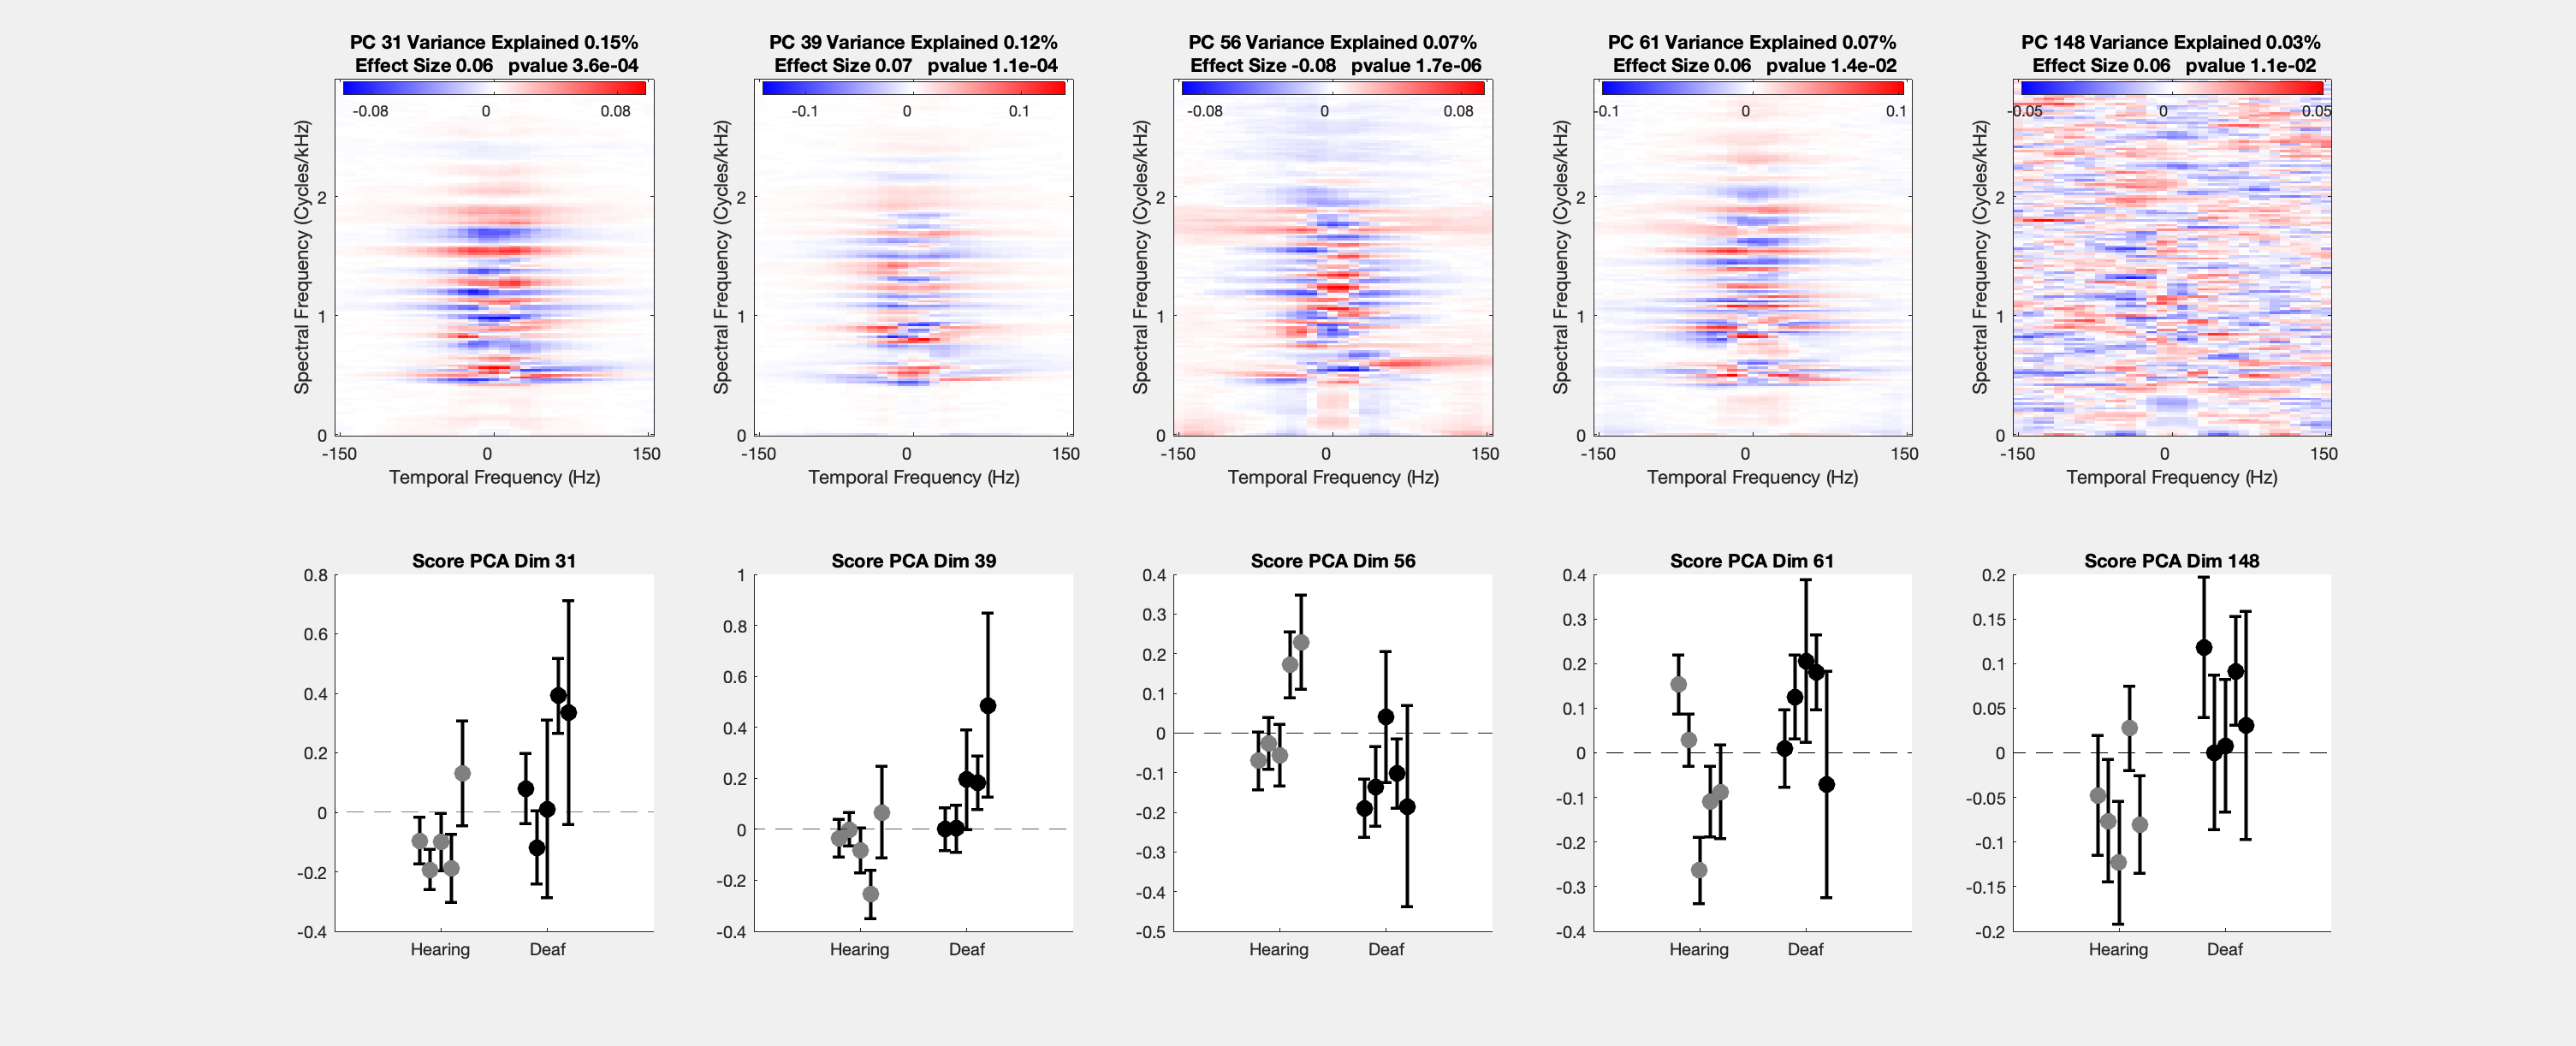

SigDim =  find(Pvalue_LME_FDR<0.05);
Fig1=figure(1);
clf(Fig1)
set(gcf,'Visible','on')
% plot the PC
for dim=1:length(SigDim)
    subplot(2,length(SigDim),dim)
    [CB3, Im3,~]=plot_mps(reshape(PC(:,SigDim(dim)),sum(IndWf),length(MPS_mic_wt)), MPS_mic_wf(IndWf), MPS_mic_wt, 60, nan, 0, [0 max(MPS_mic_wf(IndWf)*10^3)], [-150 150]);
    title(sprintf('PC %d Variance Explained %.2f%%\n Effect Size %.2f   pvalue %.1e', SigDim(dim), VarExpl(SigDim(dim)), EffectSize(SigDim(dim)),Pvalue_LME_FDR(SigDim(dim))))
    Cmap = flip([ones(128,1) (0:1/127:1)' (0:1/127:1)';
    flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)]);
    colormap(Cmap)
%     N.FontSize = 8;
end
% Plot the scores for individual bats
for dim=1:length(SigDim)
    subplot(2,length(SigDim), length(SigDim)+ dim)
    MeanScore_bats = nan(1,length(BatName));
    SEScore_bats = nan(1,length(BatName));
    for ID=1:length(BatName)
        Ind = strcmp(BatIDMic, num2str(BatName(ID)));
        MeanScore_bats(ID) = mean(Score(Ind, SigDim(dim)));
        SEScore_bats(ID) = std(Score(Ind, SigDim(dim)))/(sum(Ind))^0.5;
    end
    hold on
    errorbar((1-0.2):0.1:(1+0.2),MeanScore_bats(contains(BatSexDeaf,'Hearing')), 2*SEScore_bats(contains(BatSexDeaf,'Hearing')), 2*SEScore_bats(contains(BatSexDeaf,'Hearing')), 'k.','LineWidth',2)
    hold on
    scatter((1-0.2):0.1:(1+0.2),MeanScore_bats(contains(BatSexDeaf,'Hearing')),100, [0.5 0.5 0.5], 'filled')
    hold on
    errorbar((2-0.2):0.1:(2+0.2),MeanScore_bats(contains(BatSexDeaf,'Deaf')), 2*SEScore_bats(contains(BatSexDeaf,'Deaf')), 2*SEScore_bats(contains(BatSexDeaf,'Deaf')), 'k.','LineWidth',2)
    hold on
    scatter((2-0.2):0.1:(2+0.2),MeanScore_bats(contains(BatSexDeaf,'Deaf')),100, 'k', 'filled')
    hold on
    plot([0 3], [0 0], '--k')
    xlim([0 3])
    xticks(1:2)
    xticklabels({'Hearing', 'Deaf'})
    title(sprintf('Score PCA Dim %d', SigDim(dim)))
    hold off
end

#### Plot the significant PCs and the corresponding scores per individual and per acoustic group

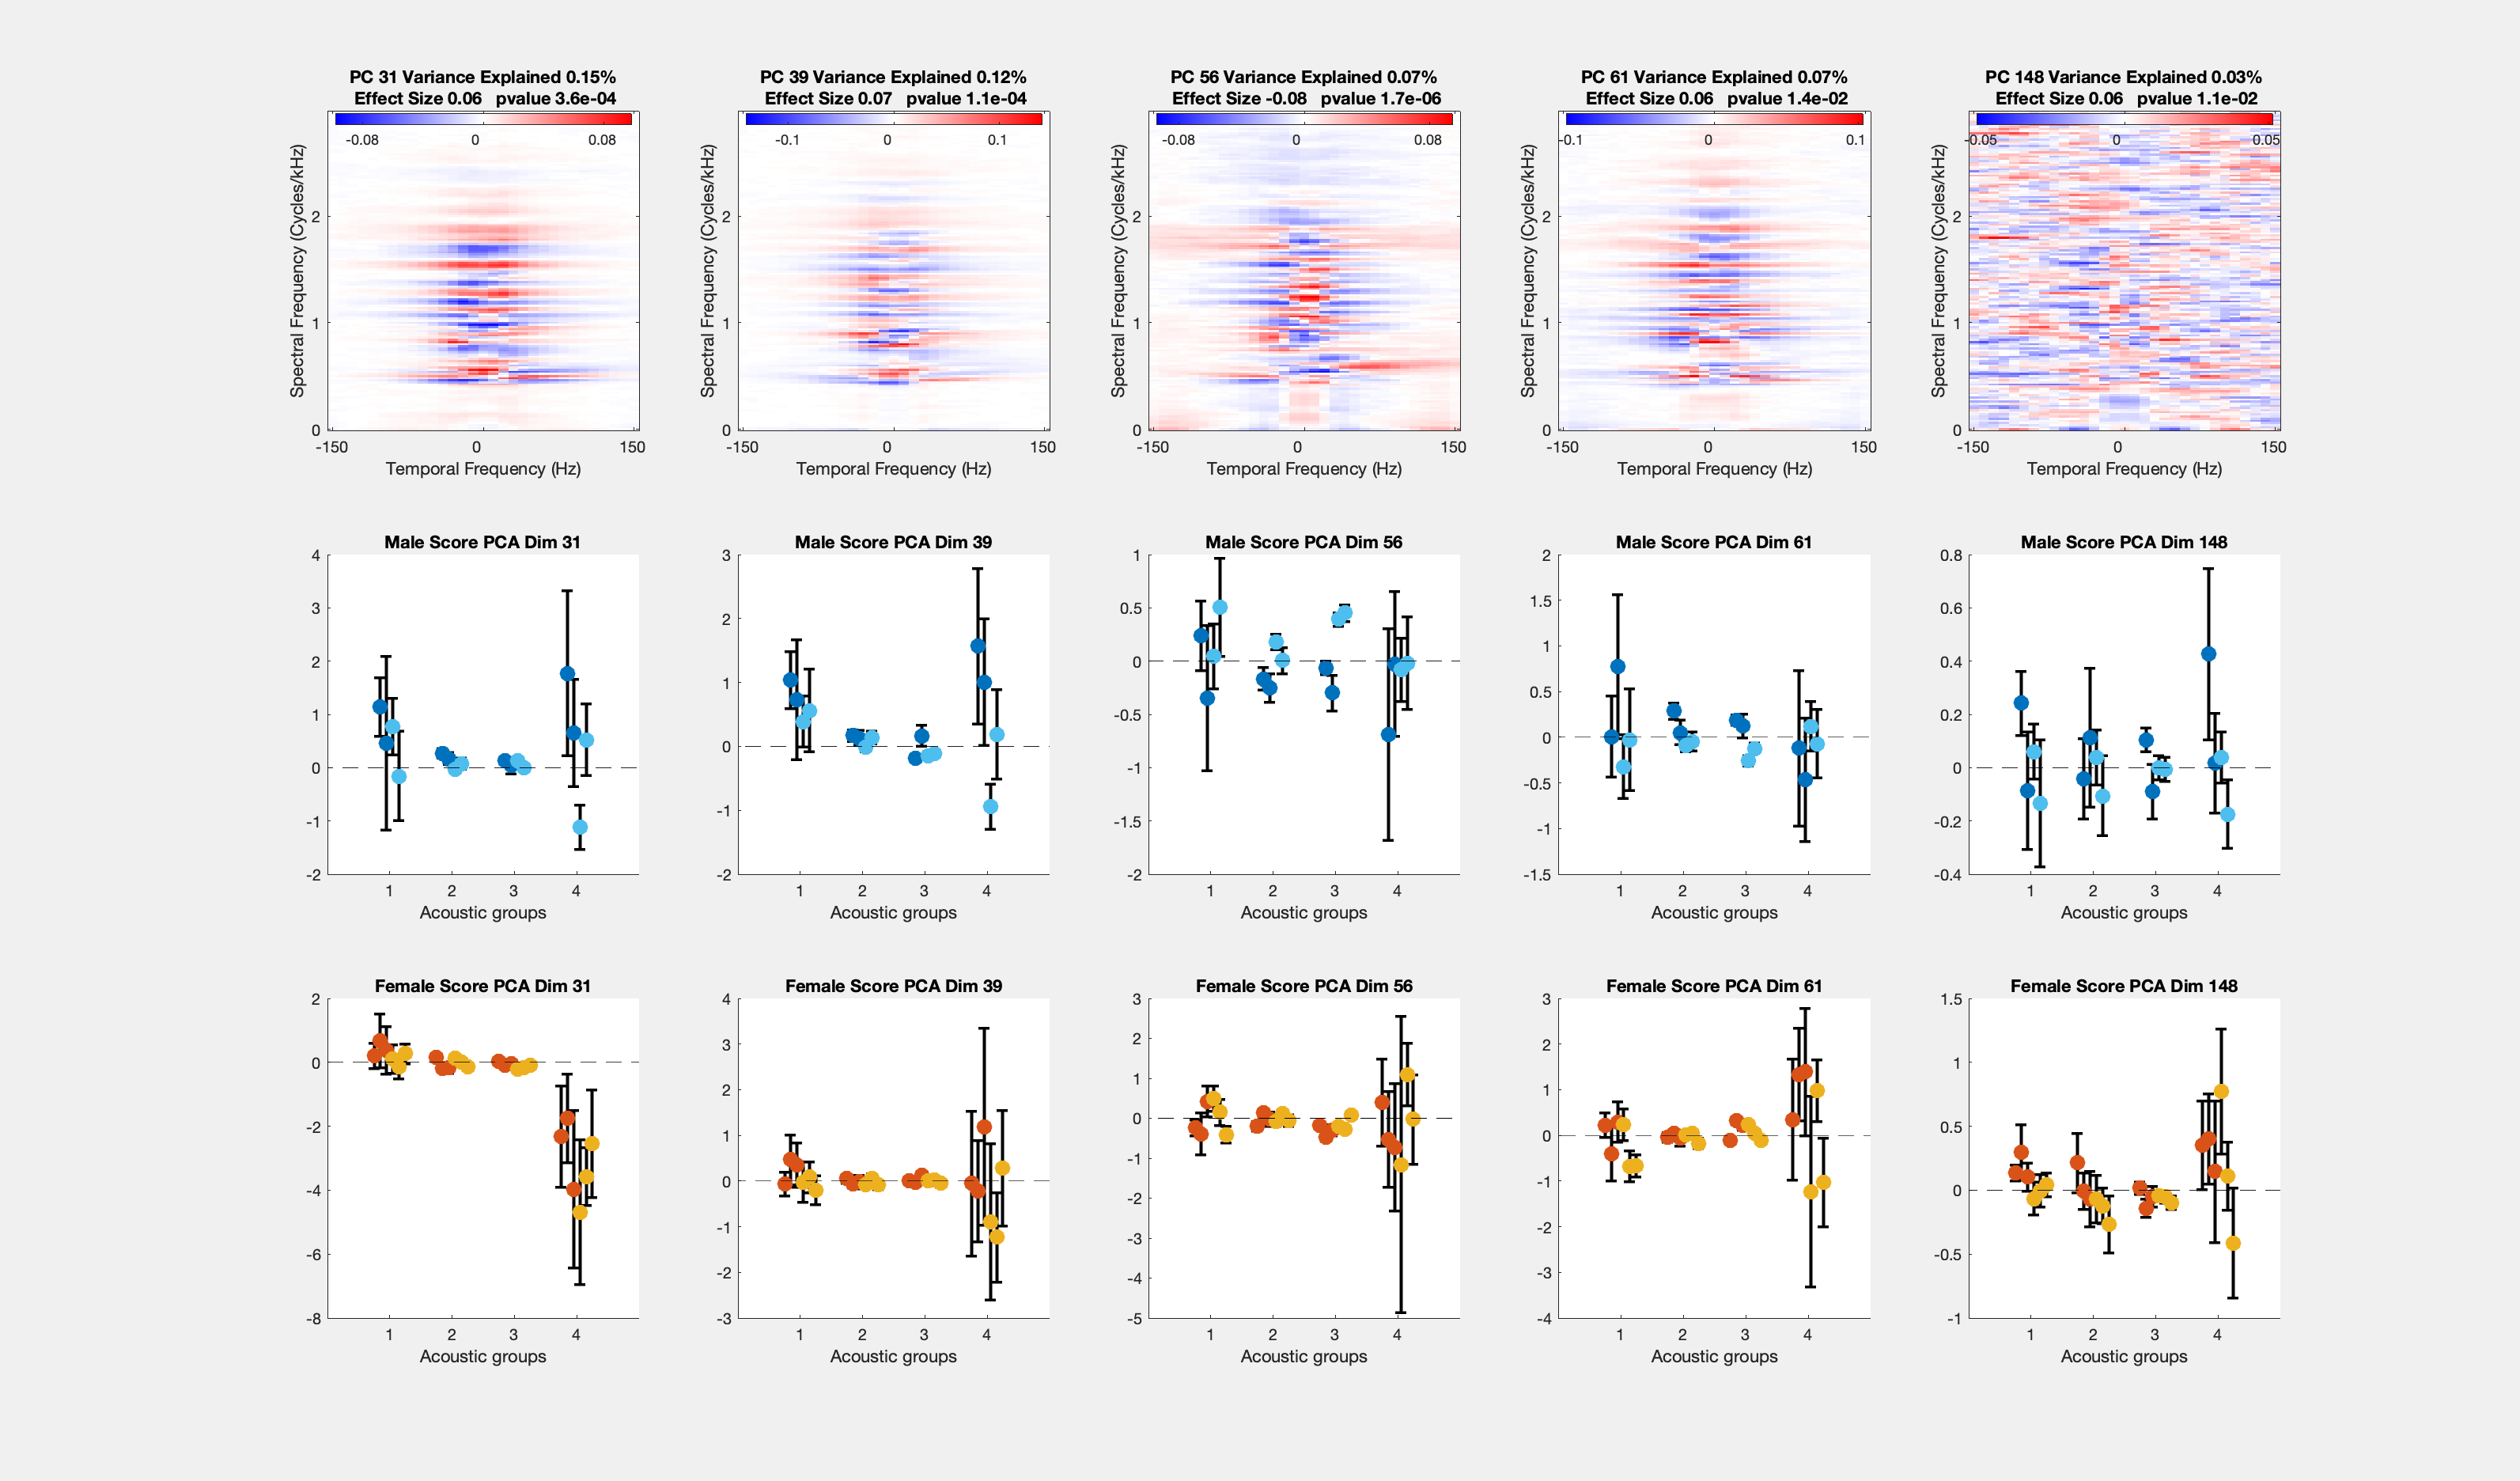

SigDim =  find(Pvalue_LME_FDR<0.05);
Fig1=figure(1);
clf(Fig1)
set(gcf,'Visible','on')
% plot the PC
for dim=1:length(SigDim)
    subplot(3,length(SigDim),dim)
    [CB3, Im3,~]=plot_mps(reshape(PC(:,SigDim(dim)),sum(IndWf),length(MPS_mic_wt)), MPS_mic_wf(IndWf), MPS_mic_wt, 60, nan, 0, [0 max(MPS_mic_wf(IndWf)*10^3)], [-150 150]);
    title(sprintf('PC %d Variance Explained %.2f%%\n Effect Size %.2f   pvalue %.1e', SigDim(dim), VarExpl(SigDim(dim)), EffectSize(SigDim(dim)),Pvalue_LME_FDR(SigDim(dim))))
    Cmap = flip([ones(128,1) (0:1/127:1)' (0:1/127:1)';
    flip(0:1/127:1)' flip(0:1/127:1)' ones(128,1)]);
    colormap(Cmap)
%     N.FontSize = 8;
end
% Plot the scores for males
MaleNames = BatName(contains(BatSexDeaf, 'Male'));
UCMaleNameSexDeaf = UCBatNameSexDeaf(contains(BatSexDeaf, 'Male'), :);
for dim=1:length(SigDim)
    subplot(3,length(SigDim), length(SigDim)+ dim)
    LocalCol = cell(1,4);
    MeanScore_Males = nan(4,4);
    SEScore_Males = nan(4,4);
    for AG = 1:4
        LocalCol{AG} = nan(4,3);
        for ID=1:length(MaleNames)
            Ind = logical(strcmp(BatIDMic, num2str(MaleNames(ID))) .* TmicAll4==AG);
            MeanScore_Males(ID,AG) = mean(Score(Ind, SigDim(dim)));
            SEScore_Males(ID,AG) = std(Score(Ind, SigDim(dim)))/(sum(Ind))^0.5;
            LocalCol{AG}(ID,:) = UCMaleNameSexDeaf(ID,:);
        end
        hold on
        errorbar((AG-0.15):0.1:(AG+0.15),MeanScore_Males(:,AG), 2*SEScore_Males(:,AG), 2*SEScore_Males(:,AG), 'k.','LineWidth',2)
        hold on
        scatter((AG-0.15):0.1:(AG+0.15),MeanScore_Males(:,AG),100, LocalCol{AG}, 'filled')
    end
    hold on
    plot([0 5], [0 0], '--k')
    xlim([0 5])
    xticks(1:4)
    xticklabels(1:4)
    xlabel('Acoustic groups')
    title(sprintf('Male Score PCA Dim %d', SigDim(dim)))
    hold off
end

% Plot the scores for females
FemaleNames = BatName(contains(BatSexDeaf, 'Female'));
UCFemaleNameSexDeaf = UCBatNameSexDeaf(contains(BatSexDeaf, 'Female'), :);
for dim=1:length(SigDim)
    subplot(3,length(SigDim), 2*length(SigDim)+ dim)
    LocalCol = cell(1,4);
    MeanScore_Females = nan(6,4);
    SEScore_Females = nan(6,4);
    for AG = 1:4
        LocalCol{AG} = nan(6,3);
        for ID=1:length(FemaleNames)
            Ind = logical(strcmp(BatIDMic, num2str(FemaleNames(ID))) .* TmicAll4==AG);
            MeanScore_Females(ID,AG) = mean(Score(Ind, SigDim(dim)));
            SEScore_Females(ID,AG) = std(Score(Ind, SigDim(dim)))/(sum(Ind))^0.5;
            LocalCol{AG}(ID,:) = UCFemaleNameSexDeaf(ID,:);
        end
        hold on
        errorbar((AG-0.25):0.1:(AG+0.25),MeanScore_Females(:,AG), 2*SEScore_Females(:,AG), 2*SEScore_Females(:,AG), 'k.','LineWidth',2)
        hold on
        scatter((AG-0.25):0.1:(AG+0.25),MeanScore_Females(:,AG),100, LocalCol{AG}, 'filled')
    end
    hold on
    plot([0 5], [0 0], '--k')
    xlim([0 5])
    xticks(1:4)
    xticklabels(1:4)
    xlabel('Acoustic groups')
    title(sprintf('Female Score PCA Dim %d', SigDim(dim)))
    hold off
end

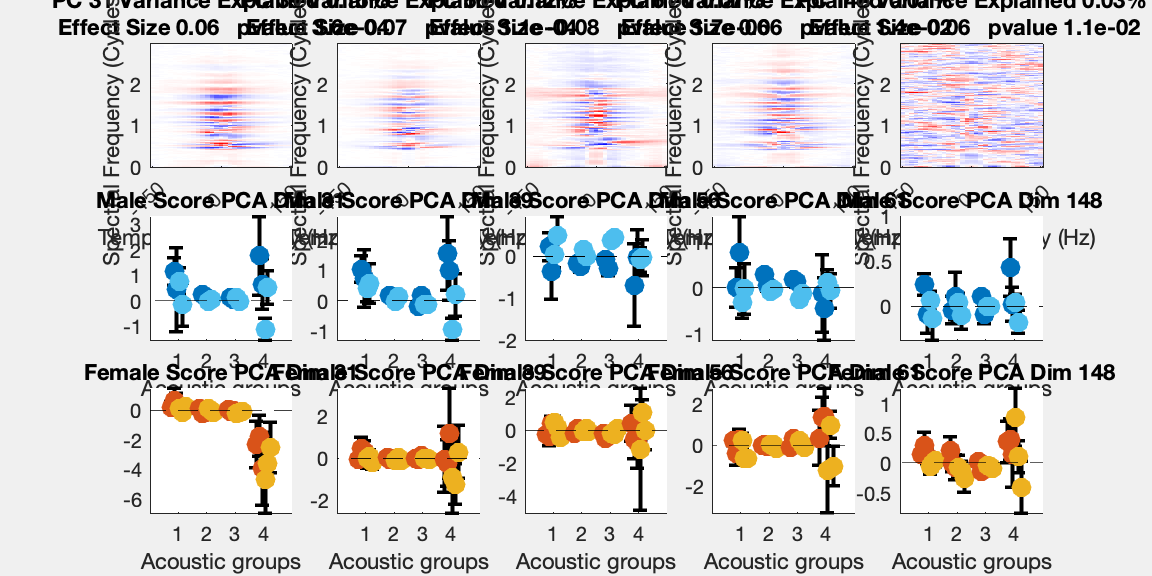

Fig1.PaperOrientation = 'landscape';
Fig1.Units = 'inches';
Fig1.Position(3:4) = [8 4];
Fig1.PaperSize = [8 4];
print(Fig1,fullfile(Path2Paper,'LME on PC dimensions'),'-dpdf','-fillpage')

function [CB,Im,MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
    if nargin<4
        DBNOISE=60;
    end

    if nargin<6
        Log=1;
    end

    if nargin<7
        YLim = [0 max(Wf*10^3)];
    end
    if nargin<8
        XLim = [min(Wt) max(Wt)];
    end
    if nargin<5
        CLim = nan;
    end
    if nargin<9
        TwoDfilter=0;
    end
    
    Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
    Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
    MPS = MPS(Wf_i, Wt_i);
    Wf_local = Wf(Wf_i);
    Wt_local = Wt(Wt_i);
    if Log
        MPS4plot = 10*log10(MPS);
        MaxMPS = max(max(MPS4plot));
        MinMPS = MaxMPS-DBNOISE;
        MPS4plot(MPS4plot < MinMPS) = MinMPS;
    else
        MPS4plot = MPS; 
    end

    if TwoDfilter
        MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
    end
    
    %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
    Im = imagesc(MPS4plot);
    MAX = max(max(abs(MPS4plot)));
    axis xy
    colormap(Im.Parent,'jet');
    caxis([-MAX MAX])
    CB=colorbar();
    YTick = CB.YTick;
    CB.YTick=[min(YTick) 0 max(YTick)];
    CB.YTickLabel=[min(YTick) 0 max(YTick)];
    CB.Units = 'inches';
    CB.Location='north';
    CB.Position(4) = 0.1;
    CB.Position(2) = CB.Position(2) + 0.2;
    
    xlabel('Temporal Frequency (Hz)')
    ylabel('Spectral Frequency (Cycles/kHz)')
    % get nice X and y tick labels
    MaxWf = max(floor(Wf_local*10^3));
    YTickLabel=0:MaxWf;
    YTick = nan(length(YTickLabel),1);
    for yy=1:length(YTick)
        YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
    end
    set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
    MaxWt = max(ceil(Wt_local*10^-1))*10^1;
    XTickLabel = [-MaxWt 0 MaxWt];
    XTick = nan(length(XTickLabel),1);
    for xx=1:length(XTick)
        [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
    end
    set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
    if ~isnan(CLim)
        PlotMPS = gca;
        PlotMPS.CLim = CLim;
    end
end

% function [CB,Im,MPS4plot, Wt_local, Wf_local]=plot_mps(MPS, Wf, Wt, DBNOISE,CLim,Log, YLim, XLim, TwoDfilter)
% if nargin<4
%     DBNOISE=60;
% end
% 
% if nargin<6
%     Log=1;
% end
% 
% if nargin<7
%     YLim = [0 max(Wf*10^3)];
% end
% if nargin<8
%     XLim = [min(Wt) max(Wt)];
% end
% if nargin<5
%     CLim = nan;
% end
% if nargin<9
%     TwoDfilter=0;
% end
% 
% Wf_i = logical((Wf*10^3>=YLim(1)).* (Wf*10^3<=YLim(2)));
% Wt_i = logical((Wt>=XLim(1)).* (Wt<=XLim(2)));
% MPS = MPS(Wf_i, Wt_i);
% Wf_local = Wf(Wf_i);
% Wt_local = Wt(Wt_i);
% if Log
%     MPS4plot = 10*log10(MPS);
%     MaxMPS = max(max(MPS4plot));
%     MinMPS = MaxMPS-DBNOISE;
%     MPS4plot(MPS4plot < MinMPS) = MinMPS;
% else
%     MPS4plot = MPS;
% end
% 
% if TwoDfilter
%     MPS4plot = imgaussfilt(MPS4plot,TwoDfilter);
% end
% 
% %             imagesc(LogMPS, interpolation='nearest', aspect='auto', origin='lower', cmap=cmap, extent=ex)
% Im = imagesc(MPS4plot);
% axis xy
% colormap(Im.Parent,'jet');
% CB=colorbar();
% %     CB.YTick=0;
% %     CB.YTickLabel=0;
% CB.Units = 'inches';
% CB.Location='north';
% CB.Position(4) = 0.1;
% CB.Position(2) = CB.Position(2) + 0.2;
% xlabel('Temporal Frequency (Hz)')
% ylabel('Spectral Frequency (Cycles/kHz)')
% % get nice X and y tick labels
% MaxWf = max(floor(Wf_local*10^3));
% YTickLabel=0:MaxWf;
% YTick = nan(length(YTickLabel),1);
% for yy=1:length(YTick)
%     YTick(yy) = find(floor(Wf_local*10^3)==YTickLabel(yy),1);
% end
% set(gca, 'YTickLabel', YTickLabel, 'YTick', YTick)
% MaxWt = max(ceil(Wt_local*10^-1))*10^1;
% XTickLabel = [-MaxWt 0 MaxWt];
% XTick = nan(length(XTickLabel),1);
% for xx=1:length(XTick)
%     [~,XTick(xx)] = min(abs(round(Wt_local)-XTickLabel(xx)));
% end
% set(gca, 'XTickLabel',XTickLabel, 'XTick', XTick)
% if ~isnan(CLim)
%     PlotMPS = gca;
%     PlotMPS.CLim = CLim;
% end
% end